# Author AUTOSAR Compositions and Components in Architecture Model

Develop AUTOSAR compositions and components for the Classic Platform by using an architecture model.

An AUTOSAR architecture model provides resources and a canvas for developing AUTOSAR composition and component models. From the architecture model, you can:

- Add and connect AUTOSAR compositions and components.

- Create architecture views for analysis.

- Link components to requirements (requires Requirements Toolbox).

- Define component behavior by creating, importing, or linking Simulink models.

- Configure scheduling and simulation.

- Export composition and component ARXML descriptions and generate component code (requires Embedded Coder).

Architecture models provide an end-to-end AUTOSAR software design workflow. In Simulink, you can author a high-level application design, implement behavior for application components, add Basic Software (BSW) service calls and service implementations, and simulate the application.

## Create Architecture Model

To begin developing AUTOSAR compositions and components in a software architecture canvas, create an AUTOSAR architecture model (requires System Composer).

1. Open the Simulink Start Page by entering the MATLAB command `simulink`.

2. On the **New** tab, scroll down to AUTOSAR Blockset and expand the list of model templates. Place your cursor over the **Software Architecture** template and click **Create Model**.

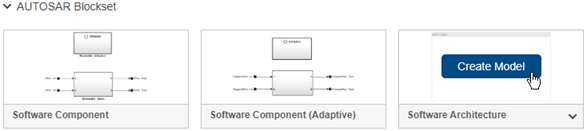

A new AUTOSAR architecture model opens.

3. Explore the controls and content in the software architecture canvas.

- In the Simulink Toolstrip, the **Modeling** tab supports common tasks for architecture modeling.

- To the left of the model window, the palette includes icons for adding different types of AUTOSAR components to the model: Software Component, Software Composition, and for Basic Software (BSW) modeling, Diagnostic Service Component and NVRAM Service Component.

- The composition editor provides a view of AUTOSAR software architecture based on the AUTOSAR Virtual Function Bus (VFB). The model canvas initially is empty.

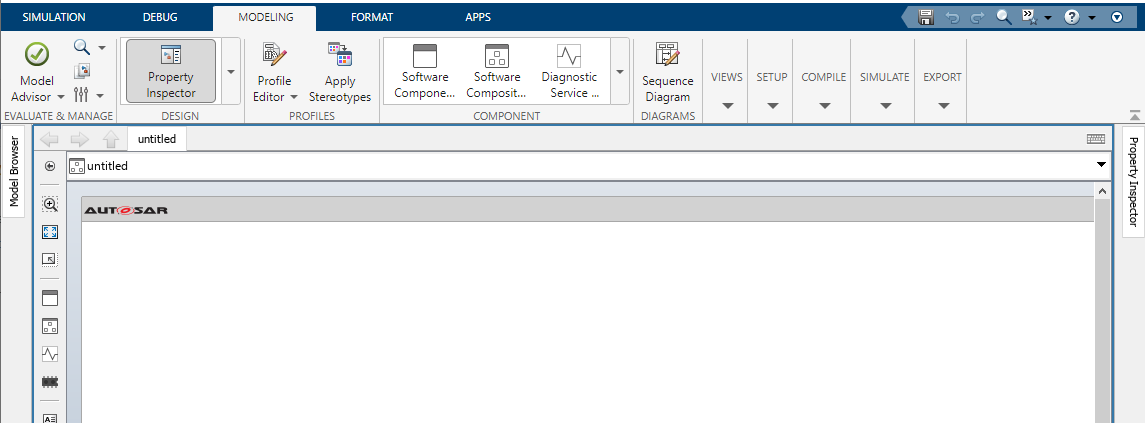

This example constructs a throttle position control application. Perform the steps in a new architecture model or refer to example model `autosar_tpc_composition`, which shows the end result.

% Open example model autosar_tpc_composition for reference
open_system('autosar_tpc_composition')

## Add Compositions and Components and Link Implementation Models

After you create an AUTOSAR architecture model, use the composition editor and the Simulink Toolstrip **Modeling** tab to add and connect compositions and components.

The behavior of the AUTOSAR application is defined by its AUTOSAR components, which you link to Simulink implementation models. For convenience, this example provides a Simulink implementation model for each AUTOSAR component:

- `autosar_tpc_throttle_sensor1.slx` for component `TPS_Primary`

- `autosar_tpc_throttle_sensor2.slx` for component `TPS_Secondary`

- `autosar_tpc_throttle_sensor_monitor.slx` for component `Monitor`

- `autosar_tpc_pedal_sensor.slx` for component `PedalSensor`

- `autosar_tpc_controller.slx` for component `Ctrl`

- `autosar_tpc_actuator.slx` for component `Actuator`

Four of the throttle position control components are sensor components, which this example places in a `Sensors` composition.

In your architecture model:

1. To create a nested `Sensors` composition, add a [Software Composition](docid:autosar_ref.bvczlz2-arcomposition) block. For example, on the **Modeling** tab, select **Software Composition** and insert a Software Composition block in the canvas. In the highlighted name field, enter `Sensors`.

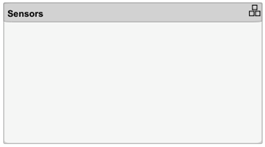

2. Open the `Sensors` block so that the model canvas shows the composition content. Inside the composition, add [Software Component](docid:autosar_ref.bvczlz2-arcomponent) blocks to represent AUTOSAR components named `TPS_Primary`, `TPS_Secondary`, `Monitor`, and `PedalSensor`. For example, on the **Modeling** tab, you can select **Software Component** to create each one.

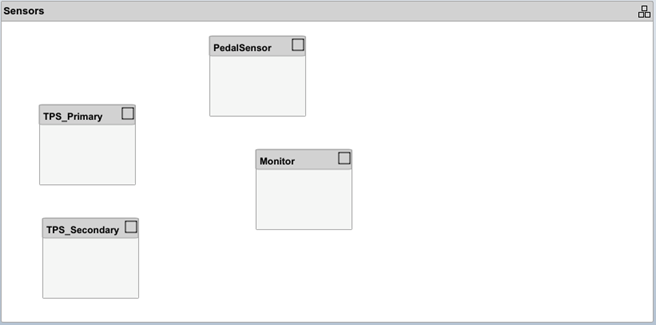

3. Link each AUTOSAR sensor component to a Simulink model that implements its behavior. For example, select the `TPS_Primary` component block, place your cursor over the displayed ellipsis, and select the cue **Link to Model**.

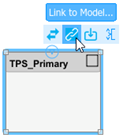

In the Link to Model dialog box, browse to the implementation model `autosar_tpc_throttle_sensor1.slx`.

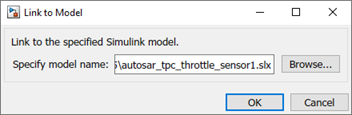

To link the component to the implementation model, click **OK**.

In an architecture model, when you initiate linking of a component block to an implementation model, the software verifies whether the specified model meets linking requirements. For example, the implementation model must use the same target as the architecture model, use a fixed-step solver, and use root-level bus ports. If the implementation model does not meet one or more of the linking requirements, the software opens the AUTOSAR Model Linker app, which offers fixes for the unmet requirements. For more information, see [Link to Implementation Model](docid:autosar_ug.mw_5881b429-06a5-4880-8231-394904860b4c).

The implementation models provided for this example meet the linking requirements.

4. After you link each model, you can resize the associated component block to better display the component ports.

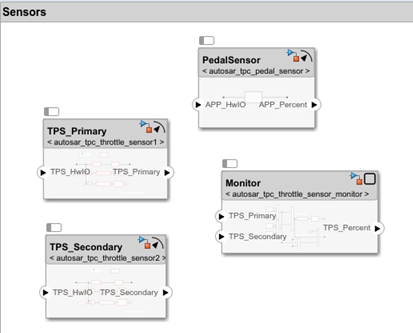

5. Connect the components to each other and to composition root ports.

- To interconnect components, drag a line from a component provider port to another component receiver port.

- To connect components to `Sensors` composition root ports, drag from a component port to the `Sensors` composition boundary.

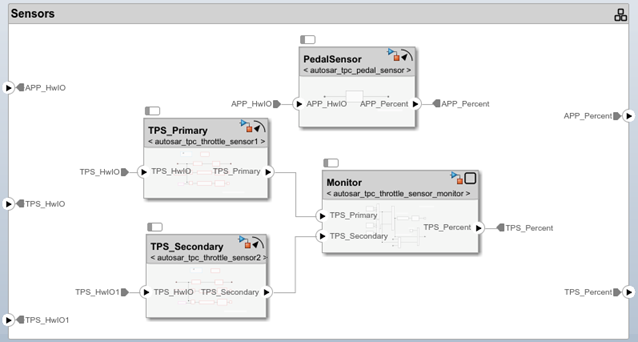

Optionally, to exactly match the root port naming in example model `autosar_tpc_composition`, rename ports `TPS_HwIO` and `TPS_HwIO1` to `TPS1_HwIO` and `TPS2_HwIO`.

6. Return to the top level of the architecture model. To complete the application, add two Software Component blocks and name them `Ctrl` and `Actuator`. Link the AUTOSAR components to their Simulink implementation models, `autosar_tpc_controller.slx `and `autosar_tpc_actuator.slx`. Connect the `Sensors` composition, `Ctrl` component, and `Actuator` component to each other and to the architecture model boundary.

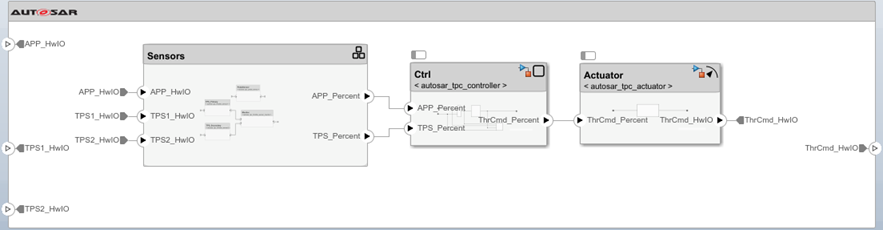

7. To check for interface or data type issues, update the architecture model. On the **Modeling** tab, select **Update Model**. If issues are found, compare your model with example model `autosar_tpc_composition.slx`.

8. Save the model with a unique name, such as `myTPC_Composition.slx`.

## Optional: Create Architecture Views for Analysis

To help analyze structural and functional aspects of an AUTOSAR architecture model, you can create a filtered view of the model hierarchy. On the **Modeling** tab, in the **Architecture Views** menu:

- Select **Spotlight** to create a spotlight view.

- Select **Architecture Views** to create a custom view with grouping criteria.

To help analyze component or composition dependencies, create a spotlight view. A spotlight view is a simplified view of an architecture component or composition that captures its upstream and downstream dependencies.

For this example, select the component `Monitor`, either in the example model `autosar_tpc_composition` or in the architecture model that you created and saved. On the **Modeling** tab, select **Architecture Views > Spotlight**.

The spotlight view opens and shows the model elements to which the component or composition connects in a hierarchy. The spotlight diagram is laid out automatically and cannot be edited.

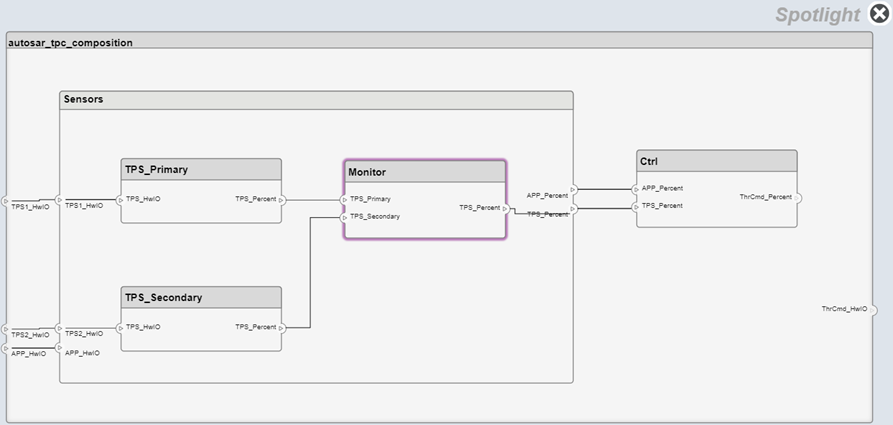

Optionally, you can create spotlight views in separate, persistent model windows. Updating the architecture model diagram with changes refreshes open spotlight views. While in spotlight view, you can move the spotlight focus.

To create a custom view with more sophisticated filtering conditions, use the Architecture Views Gallery. On the **Modeling** tab, select **Architecture Views**. Custom views can be saved with the architecture model, then accessed and shared by collaborating users. For more information, see [Create AUTOSAR Architecture Views for Analysis](docid:autosar_ug.mw_1db1317f-6f2a-453e-ad60-df71c30c4f31).

## Optional: Link Components to Requirements (Requirements Toolbox)

If you have Requirements Toolbox software, you can link components in the architecture model to Simulink requirements. The example folder provides sample requirements file `TPC_Requirements.slreqx`. The file contains requirements for four of the throttle position control application components.

To link a component to a requirement:

1. Open the **Requirements Manager** app. In the architecture model window, the **Requirements** tab opens, with the Requirements Browser docked at the bottom.

2. In the Requirements Browser, open requirements set `TPC_Requirements.slreqx`. The requirements set contains requirements for four components in the model.

3. To link an AUTOSAR component to a requirement, drag the requirement from the Requirements Browser to the component block. For example, drag requirement 4 to the `Actuator` component block.

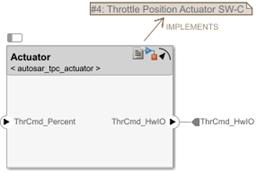

For more information, see [Link AUTOSAR Components to Simulink Requirements](docid:autosar_ug.mw_3bc38b9b-1919-4ca4-88a8-840bd4876b84).

## Configure and Run Simulation

To simulate the behavior of the aggregated components in an AUTOSAR architecture model, click **Run**.

If you try to run the architecture model constructed in this example, an error message reports that a function definition was not found for a Basic Software (BSW) function caller block. Three of the component implementation models contain BSW function calls that require BSW service implementations.

To view those function calls, open your architecture model, for example, `myTPC_Composition.slx`. On the **Debug** tab, select **Information Overlays** > **Function Connectors**. This selection lists function connectors for each model with functions. To see the models with BSW function calls, open the `Sensors` composition.

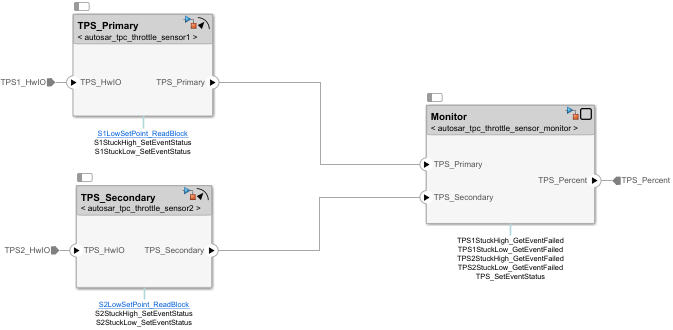

The models contain function calls to Diagnostic Event Manager (Dem) and NVRAM Manager (NvM) services. Before the application can be simulated, you must add [Diagnostic Service Component](docid:autosar_ref.bvczlz2-1diag) and [NVRAM Service Component](docid:autosar_ref.bvczlz2-1mem) blocks to the top model.

To add and configure the service implementation blocks:

1. Return to the top level of the architecture model and select the **Modeling** tab. Select and place an instance of **Diagnostic Service Component** and an instance of **NVRAM Service Component**. To wire the function callers to the BSW service implementations, update the model.

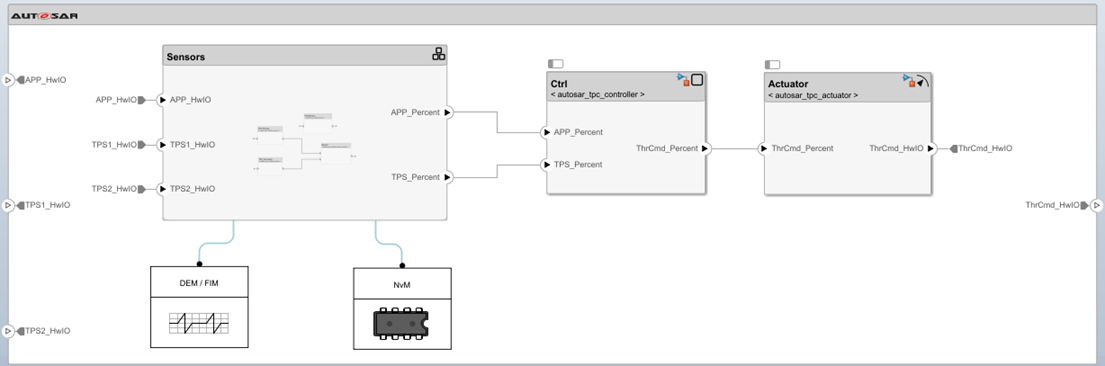

2. Check the mapping of the BSW function-caller client ports to BSW service IDs. Dem client ports map to Dem service event IDs and NvM client ports map to NvM service block IDs.

For this example, update the Dem mapping. Open the DEM/FIM block dialog box, select the **RTE** tab, and enter the event ID values shown. Click **OK**. For more information about BSW ID mapping, see [Simulate AUTOSAR Basic Software Services and Runtime Environment](docid:autosar_ug.mw_9ba679b1-2058-4d06-b7a1-357950a01ae8).

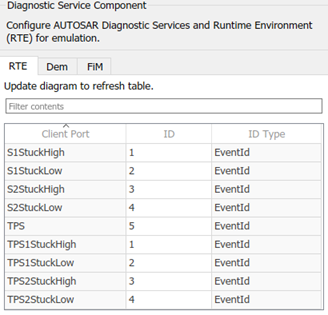

The architecture model is now ready to be simulated. Click **Run**.

## Connect Architecture Model to Test Harness Containing Plant Model and Pedal Input

To provide simulated pedal input to the throttle position control simulation, you can place the architecture model in a test harness model. The test harness can provide a plant model with a pedal input block. Refer to example test-harness model `autosar_tpc_system.slx`.

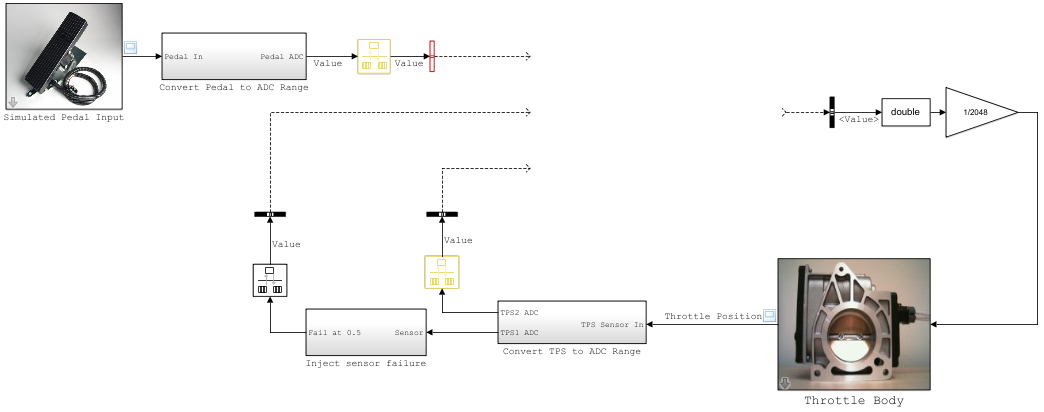

To connect the architecture model to the test harness:

1. Insert a Model block.

2. Configure the Model block to reference your architecture model, for example, `myTPC_Composition.slx`.

3. In the Model block dialog box, select the option **Schedule rates**. For the associated parameter **Schedule rates with**, select `Schedule Editor`. The throttle position control components have explicit partitions that you can schedule with the Schedule Editor.

4. Connect the architecture model ports to the test harness signals.

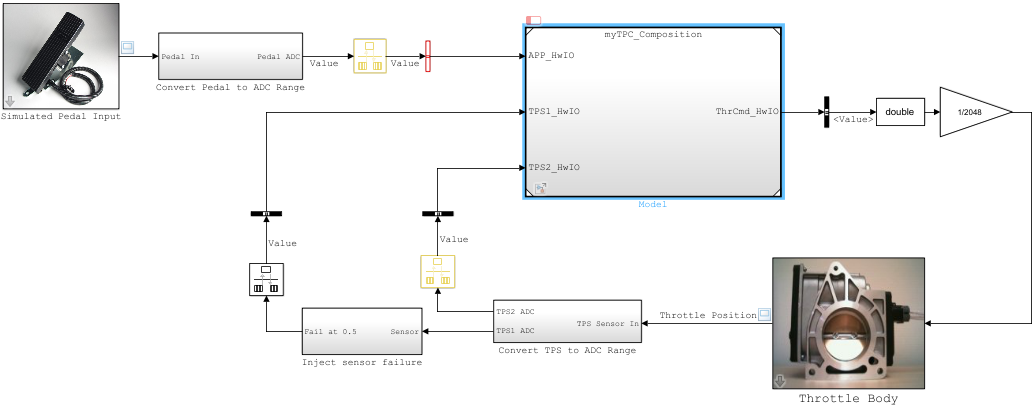

The test harness model is now ready to be simulated. Click **Run**. When you simulate the application, the throttle position scope indicates how well the throttle-position control algorithms in the architecture model are tracking the accelerator pedal input.

In a test harness model, from the Model block for a referenced AUTOSAR architecture model, you can use the Schedule Editor to schedule rates for component runnables. To open the Schedule Editor, click the Schedule Editor badge immediately above the Model block. In the Schedule Editor display, you can visualize and control the order of execution of the runnables (partitions) in the application components. For more information, see [Using the Schedule Editor](docid:simulink_ug.mw_69698928-e238-4261-828e-87927c5cb210), [Configure AUTOSAR Runnable Execution Order By Using Schedule Editor](docid:autosar_ug.mw_961ed142-79e9-457f-991d-f91cfa369f63), and [Configure AUTOSAR Scheduling and Simulation](docid:autosar_ug.mw_2afcc3ce-18e9-4c96-b24e-10a1edad4d66).

## Generate and Package Composition ARXML Descriptions and Component Code (Embedded Coder)

If you have Simulink Coder and Embedded Coder software, you can export composition and component AUTOSAR XML (ARXML) descriptions and generate component code from an AUTOSAR architecture model. Optionally, create a ZIP file to package build artifacts for the model hierarchy, for example, for relocation and integration. 

To export ARXML files and generate code:

1. Open the architecture model constructed in this example or open example model a`utosar_tpc_composition.slx`.

2. To prepare for exporting ARXML, examine and modify XML options. On the **Modeling** tab, select **Export** > **Configure XML Options**. The AUTOSAR Dictionary opens in the XML Options view. XML options specified at the architecture model level are inherited during export by each component in the model.

3. To generate and package code for the throttle position control application, on the **Modeling** tab, select **Export** > **Generate Code and ARXML**. In the Export Composition dialog box, specify the name of the ZIP file in which to package the generated files. To begin the export, click **OK**.

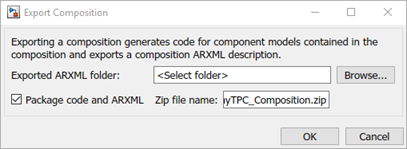

As the architecture model builds, you can view the build log in the Diagnostic Viewer. First the component models build, each as a standalone top-model build. Finally, composition ARXML is exported. When the build is complete, the current folder contains build folders for the architecture model and each component model in the hierarchy, and the specified ZIP file.

4. Expand the ZIP file. Its content is organized in `arxml` and `src` folders.

5. Examine the `arxml` folder. Each AUTOSAR component has component and implementation description files, while the architecture model has composition, datatype, interface, and timing description files. The composition file includes XML descriptions of the composition, component prototypes, and composition ports and connectors. The datatype, interface, and timing files aggregate elements from the entire architecture model hierarchy. Nonfunctional properties captured in stereotypes and profiles are not included in the description files.

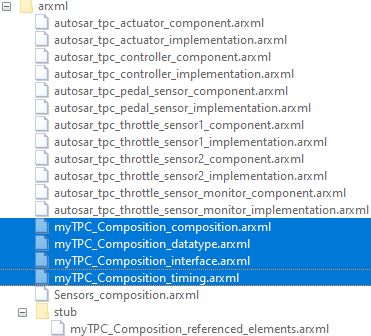

6. Examine the `src` folder. Each component model has a build folder that contains artifacts from a standalone model build.

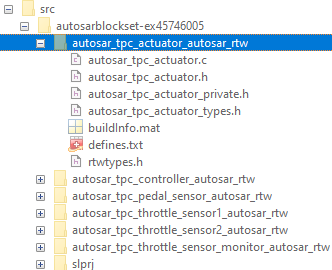

## Related Links

- [Create AUTOSAR Architecture Models](docid:autosar_ug.mw_d74bc954-8733-4474-9999-3655be48faf1)

- [Add and Connect AUTOSAR Compositions and Components](docid:autosar_ug.mw_af506671-2ea8-4273-8e1a-35658887cd2d)

- [Create AUTOSAR Architecture Views for Analysis](docid:autosar_ug.mw_1db1317f-6f2a-453e-ad60-df71c30c4f31)

- [Link AUTOSAR Components to Simulink Requirements](docid:autosar_ug.mw_3bc38b9b-1919-4ca4-88a8-840bd4876b84)

- [Define AUTOSAR Component Behavior by Creating or Linking Models](docid:autosar_ug.mw_b4636306-043f-4508-a03c-3b128606ca7a)

- [Configure AUTOSAR Scheduling and Simulation](docid:autosar_ug.mw_2afcc3ce-18e9-4c96-b24e-10a1edad4d66)

- [Generate and Package AUTOSAR Composition XML Descriptions and Component Code](docid:autosar_ug.mw_88a514a5-82b5-475b-8a4d-cd4253c84eaf)

*Copyright 2020 The MathWorks, Inc.*